# Create difference of two rectangles



% Define the vertices of the two rectangles
rect1 = [0, 0; 0, 5; 10, 5; 10, 0]; % Vertices of rectangle 1
rect2 = [5, 1; 5, 4; 14, 4; 14, 1]; % Vertices of rectangle 2

% Create polyshapes from the rectangles
poly1 = polyshape(rect1);
poly2 = polyshape(rect2);

% Find the difference between the two polyshapes
differencePoly = subtract(poly1, poly2);

% Get the vertices of the resulting polygon
differenceVertices = differencePoly.Vertices;

% Display the difference vertices
disp('Difference vertices:');

Difference vertices:


disp(differenceVertices);

     0     0
     0     5
    10     5
    10     4
     5     4
     5     1
    10     1
    10     0



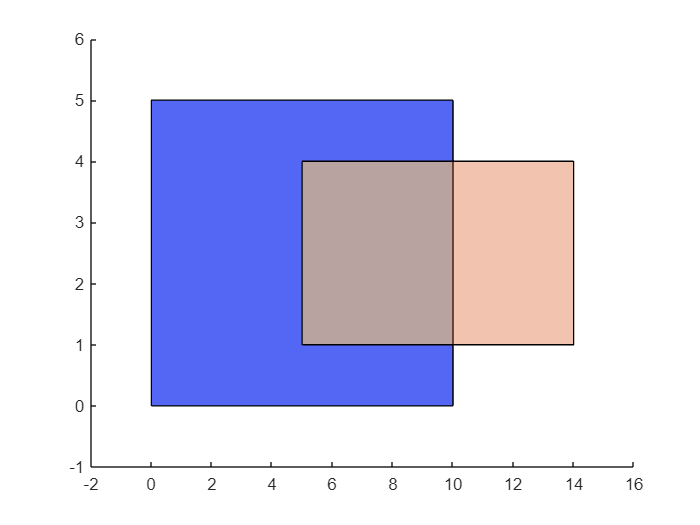


% Plot the rectangles and their difference
figure;
plot(poly1);
hold on;
plot(poly2);
plot(differencePoly, 'FaceColor', 'blue', 'FaceAlpha', 0.5);